# Organize and Analyze Training Data

clear vars; close all; clc;
NUM_NODES = 1628;
OUTPUT_NODE = 1354;
MAX_PCA_MODES = 100;

% Set parameters
dt = 0.001;
T = 3.0;
sample_rate = 1; % In milliseconds

N = T / dt;
Tspan = linspace(0,T,N);
N_divisible = allDivisors(N);
[~, sample_batch] = min(abs(N_divisible - sample_rate));

## Pick Training Data and Consolidate

[files,path] = uigetfile('*.csv',...
   'Select One or More Files', ...
   'MultiSelect', 'on');

% Data is stored in 'modal_trajectory_data/output/'
[filePath, xData] = consolidateData(path, files, Tspan, NUM_NODES, sample_batch, 'storeType', 'both');

Load Data:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf it/s]


## PCA on Consolidated Data

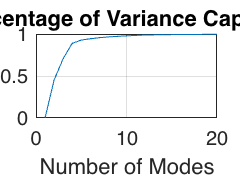

[V, S] = PCA(xData, MAX_PCA_MODES);

maxNumModes = 20;
modes = linspace(1, maxNumModes, maxNumModes);
energyFunc = @(x) sum(S(x:end).^2) / sum(S.^2);

figure;
plot(modes, 1 - arrayfun(energyFunc, modes));
grid on;
title('Percentage of Variance Captured');
xlabel('Number of Modes');